%prep 1
clf
s=tf("s");
G = 32/(s+8)

G =
 
   32
  -----
  s + 8
 
Continuous-time transfer function.
Model Properties


%bode(G)
hold on
%Kp = 2
%bode(G*Kp)
Kp = 0.5

Kp = 0.5000

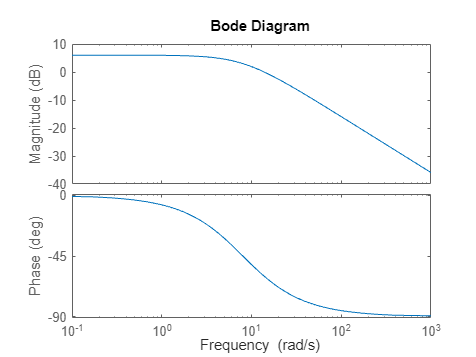

bode(G*Kp)

%prep4
clf
G = 8/(s*(s/10+1))

G =
 
      80
  ----------
  s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


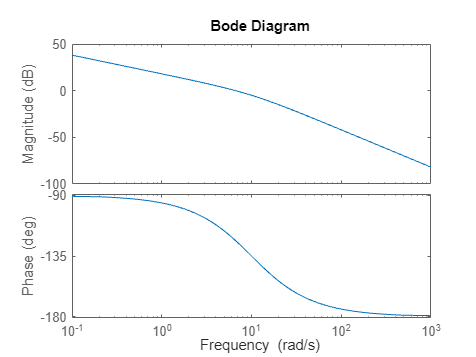

bode(G)

% Wc = 6.66 => Phase margin = 56.3    (-123.7)
% Fig 5.11 gives zeta = 0.5
% Fig 5.12 gives WcTr = 1.29   Tr <= 0.06s gives
% Wc,d = 21.5 => -155 deg Phase margin,c,d = 25
% need to add 56.3-25 = 31.3 
% 31.3 + 8 (from the lag)
% ?
% ?
% 1/|Flead||G(i*21.5)| =  1/0.34 = 2.9
Kp = 2.9 % 
F = Kp

F = 0.5000

%F = K * ((D*s+1)/(b*D*s+1)) * ((I*s+1)/(I*s+y))